Define Physical Constants

%constants constants
c = physconst('LightSpeed');

Fs_FMCW = 20e9;  %This is used to "sample" the continupus FMCW Waveform that we are transmitting and receiving,
                    %since the FMCW signal created by matlab has a
                    %frequency of roughly 4 GHz, sampling at 20 to get a
                    %good continuous waveform

Fs_ADC_desired = 18e6;   %18 Msps - the maximum complex sample rate on the IWR1443
                %Note: leave sample rate the same for the purposes of the
                %simulation in MATLAB. In practice this would vary

## Defender Setup

Set up key FMCW chirp paramters:

- chirp cycle time

- frequency slope

- samples per chirp

- sampling rate

- sampling period

- sweep bandwidth

- starting frequency

defender = struct;

%frequency and wavelength
defender.fc = 77e9;                         %Hz
defender.lambda = c/defender.fc;            %m

%chirp information - set the following parameters

defender.frequency_slope = 65;              %MHz/us
defender.chirp_cycle_time = 67.85e-6;       %s
defender.idle_time = 7e-6;                  %s
defender.adc_valid_start_time = 6.30e-6;    %s


%chirp information - calculated values
defender.ramp_end_time = defender.chirp_cycle_time ...
                        - defender.idle_time;               %s
defender.sampling_period = defender.ramp_end_time ...
                        -defender.adc_valid_start_time...
                        -1e-6;                              %s
defender.sampling_rate = Fs_FMCW;                           %sps
defender.samples_per_chirp = ceil(defender.sampling_period * defender.sampling_rate);
defender.sampling_period = defender.samples_per_chirp ...
                        /defender.sampling_rate;            %s      (this is done as a subtle readjustment of the sampling rate so that the number of samples is an integer)
defender.sampling_bandwidth = defender.sampling_period...
                        *defender.frequency_slope *1e12;    %Hz

%provide other diagnostic information - FOR DIAGNOSTIC ONLY DO NOT USE
defender.chirp_bw = defender.ramp_end_time ...
                        * defender.frequency_slope * 1e12;  %Hz      (this is the actual BW of a chirp)
defender.Fs_for_256_samples_per_chirp = 256 ...
                        / defender.sampling_period;         %Hz

Next, setup the waveform using the, "phased.FMCWWaveform" function which requires the following paramters:

- SampleRate (Hz)

- SweepTime (s)

- SweepBandwidth (Hz)

- SweepDirection

- SweepInterfal - 'Positive' to sweep from 0 to B

- OutputFormat - output either a number of 'Sweeps' or 'Samples'

- NumSamples or NumSweeps

num_sweeps = 1;
defender.waveform = phased.FMCWWaveform( ...
                                'SampleRate', defender.sampling_rate, ...
                                'SweepTime', defender.sampling_period,...
                                'SweepBandwidth', defender.sampling_bandwidth, ...
                                'SweepDirection', 'Up',...
                                'SweepInterval', 'Positive',...
                                'OutputFormat','Sweeps',...
                                'NumSweeps',num_sweeps);

Plot the waveform in time and in the form of a spectogram. The "spectogram" funciton has the following parameters:

- x - input signal (the waveform)

- window - signal is divided into windows of length (512) samples

- noverlap - uses (256) overlap samples between adjoining segments

- nfft - uses (32) samples to perform the fft

- Fs_FMCW - the sampling rate that the data was taken at

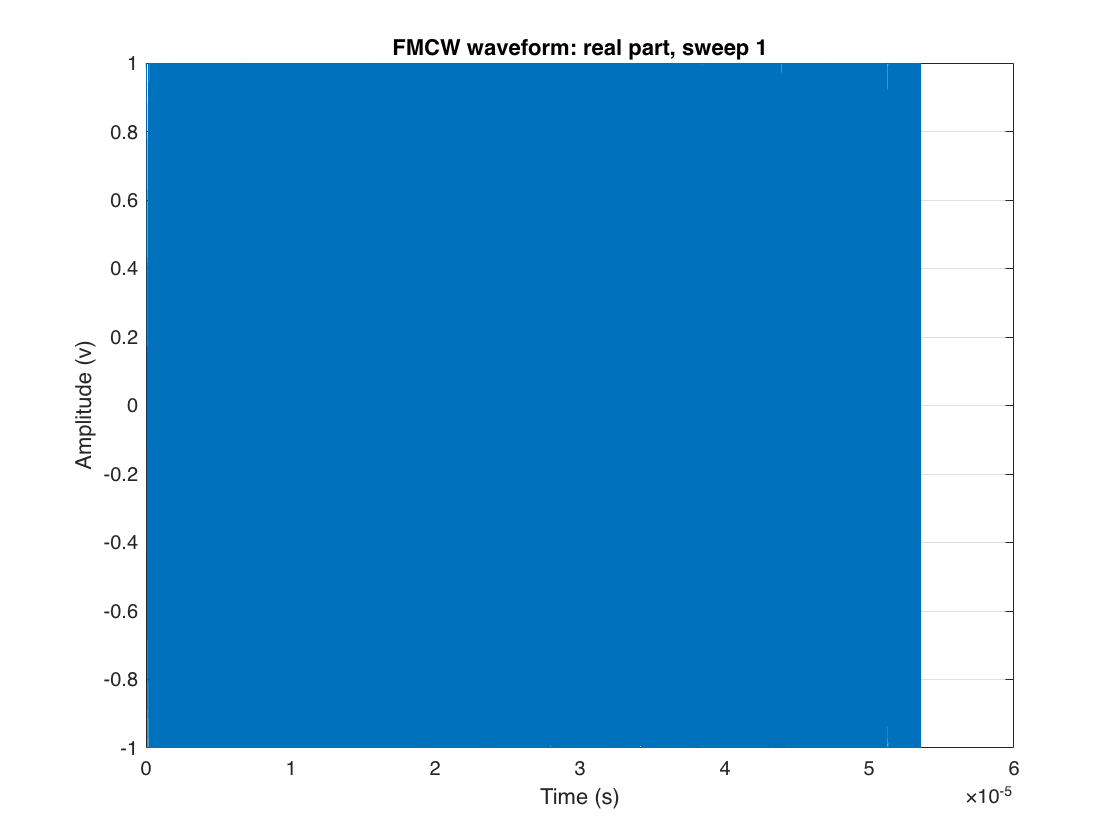

%time plot
plot(defender.waveform);        %this plot won't show anything since the final output has a frequency in the GHz region

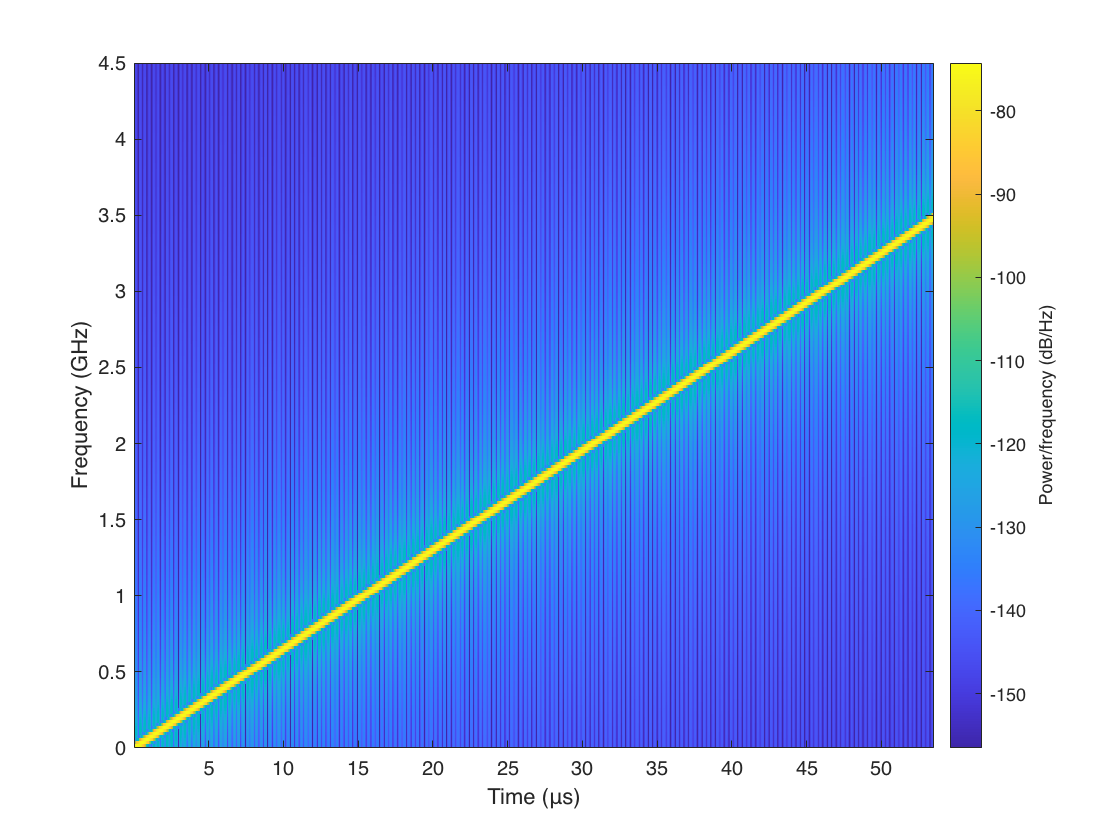


%spectogram
defender.signal = defender.waveform();
windowlength = 1028;
noverlap = 512;
nfft = 1028;
spectrogram(defender.signal,windowlength,noverlap,nfft,defender.sampling_rate, 'yaxis');
ylim([0 4.5])

## Target Generation

Next we seek to generate a target so that we can examine the affect that our attacker may or may not have on the defender

%create a target object
target = struct;
%set desired range of the target

target.range = 10;              %m

%calculate the time delay for the target
target.time_delay = range2time(target.range,c);     %s
target.delay_in_samples = ceil(Fs_FMCW * target.time_delay);

%shift the defenders signal by the number of samples and then clip it to
%make sure that its the same number of samples

target.signal = zeros(defender.samples_per_chirp,1);
target.signal(target.delay_in_samples + 1: end) = ...
                defender.signal(1:(defender.samples_per_chirp - target.delay_in_samples));

Next we plot the target's return signal to see what it looks like:

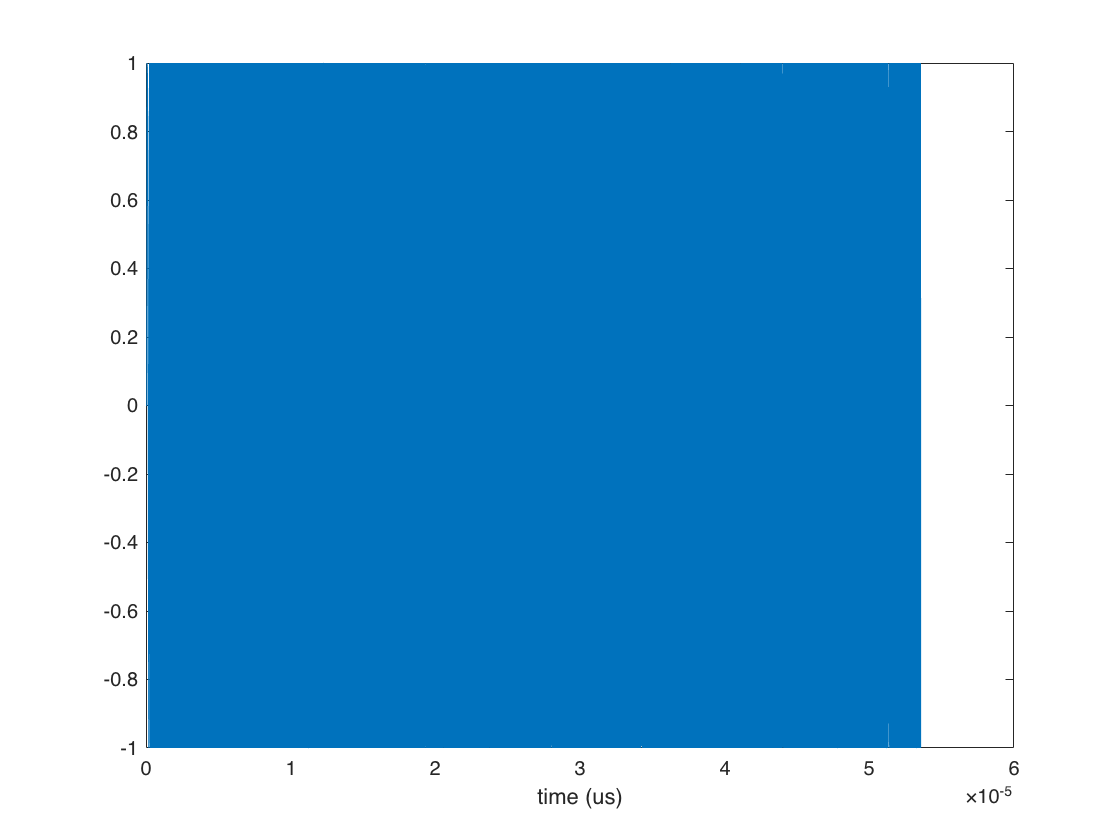

%time plot
t = 0:1/Fs_FMCW:defender.sampling_period - 1/Fs_FMCW;
plot(t,real(target.signal)); 
xlabel('time (us)');

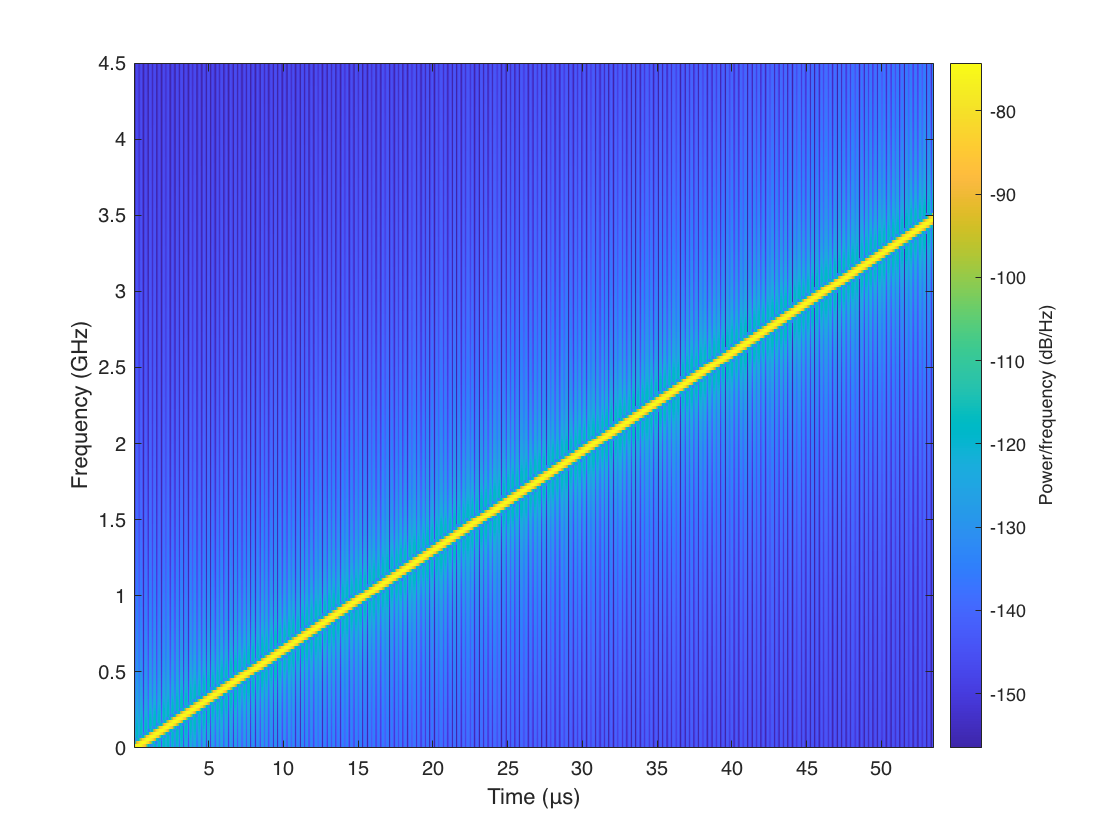


%spectogram
windowlength = 1028;
noverlap = 512;
nfft = 1028;
spectrogram(target.signal,windowlength,noverlap,nfft,Fs_FMCW, 'yaxis');
ylim([0 4.5])

## Range Estimation

Next, we dechirp the signal and look to see if we get a range on the target.

received_signal = dechirp(target.signal,defender.signal);

We down sample the received signal as if it was being read by the ADC and DAC

%determine the nearest integer sampling factor by which to down sample the
%signal
down_sample_factor = ceil(Fs_FMCW/Fs_ADC_desired);
Fs_ADC_actual = Fs_FMCW / down_sample_factor;
received_signal_downsampled = downsample(received_signal,down_sample_factor);

Plot the received signal

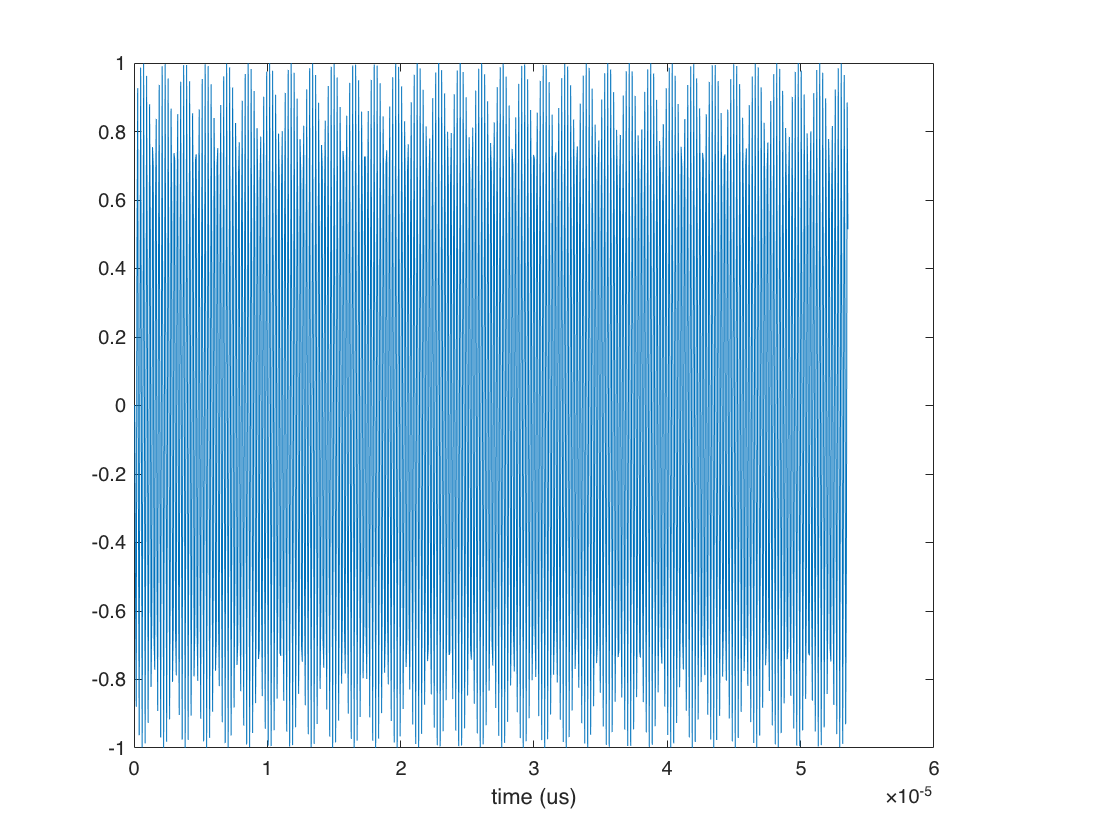

%time plot
ADC_sample_period = 1/Fs_ADC_actual;
num_downsampled_samples = ceil(defender.samples_per_chirp/down_sample_factor);
t = 0:ADC_sample_period:ADC_sample_period * (num_downsampled_samples-1);
plot(t,real(received_signal_downsampled)); 
xlabel('time (us)');

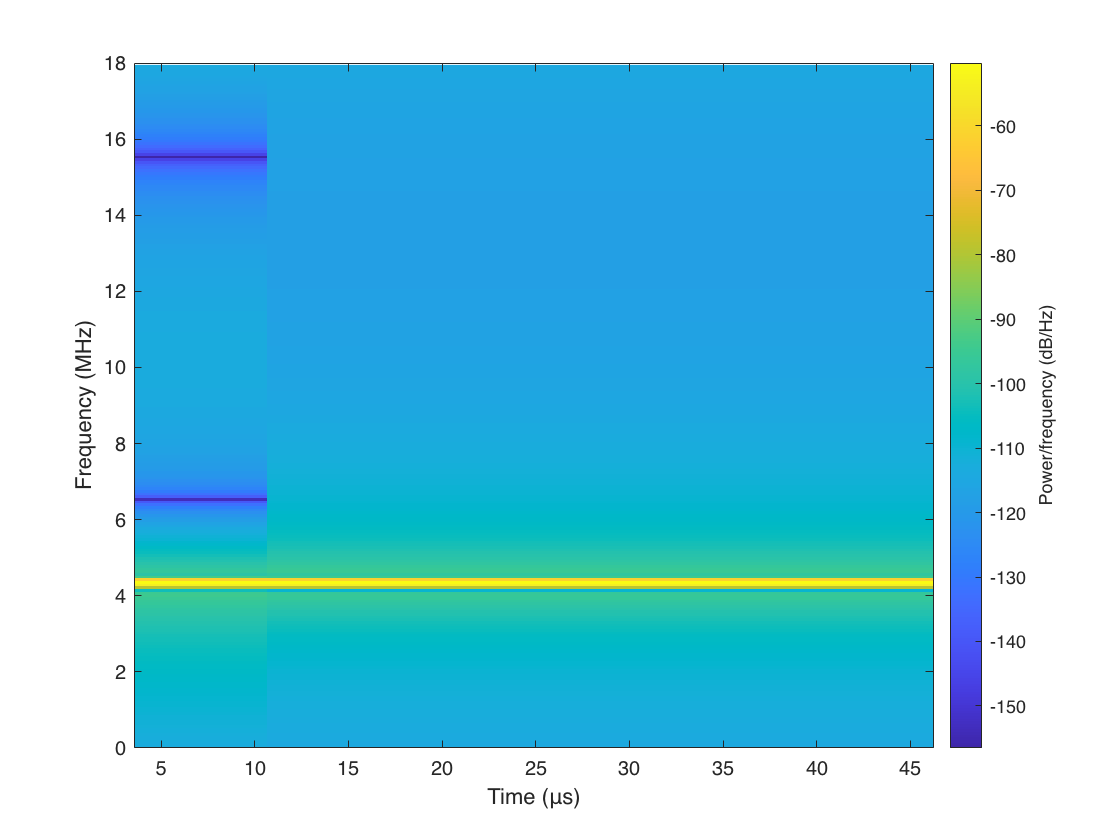

%spectogram
windowlength = 256;
noverlap = 128;
nfft = 256;
spectrogram(received_signal_downsampled,windowlength,noverlap,nfft,Fs_ADC_actual, 'yaxis');
ylim([0 18])

The spectograph clearly shows that we have a return, next we calculate the fft and determine the range of the target to confirm that we have accurately processed the signal:

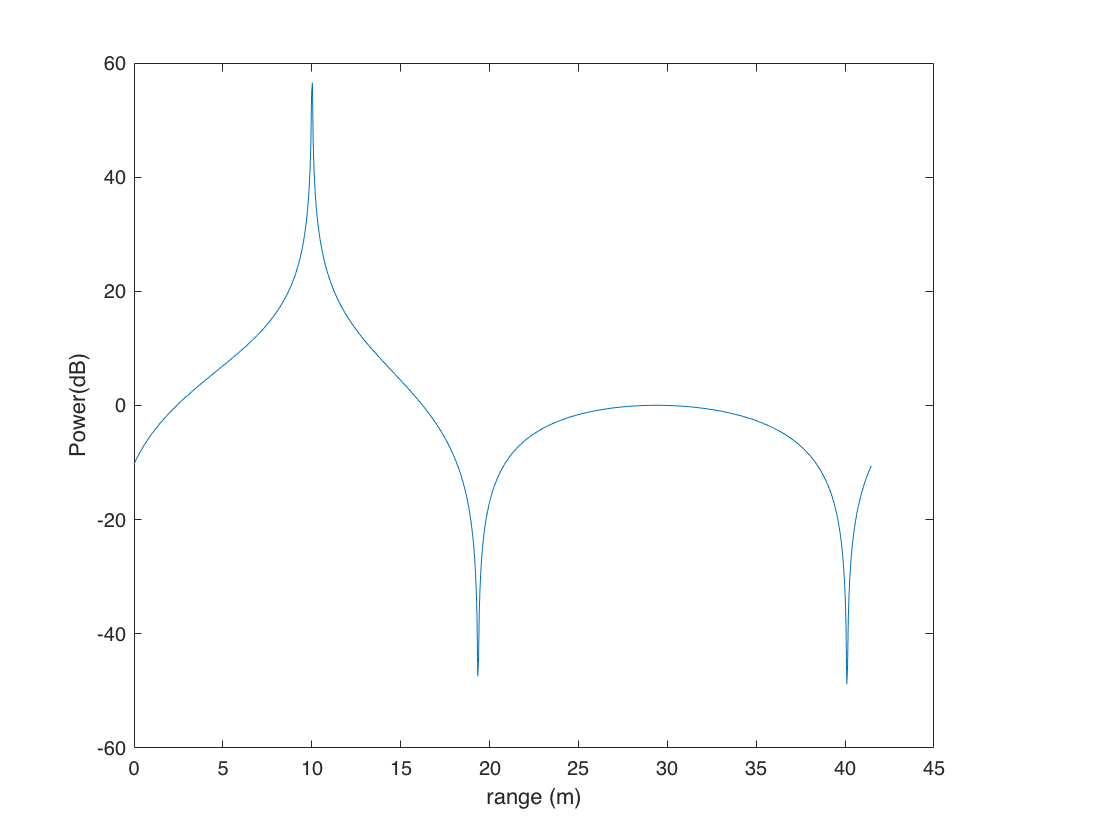

range_resolution = c/2/defender.sampling_bandwidth;
ranges = (0:num_downsampled_samples - 1) * range_resolution;

fft_out = 20 * log10(abs(fft(received_signal_downsampled)));
plot(ranges,fft_out)
ylabel("Power(dB)");
xlabel("range (m)");

While we get an interesting fft plot overall, its still clear that we are getting a peak at the distance of the point which is good overall.

**NOTE: TRY AND UNDERSTAND WHY THE FFT PLOT HAS SUCH AN INTERESTING SHAPE**

## **Constructing a false positive attack**

### **Constructing the Attacker**

The initial assumption is that the attacker has the same chirp characteristics as the defender.

Set up key FMCW chirp paramters:

- chirp cycle time

- frequency slope

- samples per chirp

- sampling rate

- sampling period

- sweep bandwidth

- starting frequency

attacker = struct;

%frequency and wavelength
attacker.fc = 77e9;                         %Hz
attacker.lambda = c/attacker.fc;            %m

%chirp information - set the following parameters

attacker.frequency_slope = 65;              %MHz/us
attacker.chirp_cycle_time = 67.85e-6;       %s
attacker.idle_time = 7e-6;                  %s
attacker.adc_valid_start_time = 6.30e-6;    %s


%chirp information - calculated values
attacker.ramp_end_time = attacker.chirp_cycle_time ...
                        - attacker.idle_time;               %s
attacker.sampling_period = attacker.ramp_end_time ...
                        -attacker.adc_valid_start_time...
                        -1e-6;                              %s
attacker.sampling_rate = Fs_FMCW;                                %sps
attacker.samples_per_chirp = ceil(attacker.sampling_period * attacker.sampling_rate);
attacker.sampling_period = attacker.samples_per_chirp ...
                        /attacker.sampling_rate;            %s      (this is done as a subtle readjustment of the sampling rate so that the number of samples is an integer)
attacker.sampling_bandwidth = attacker.sampling_period...
                        *attacker.frequency_slope *1e12;    %Hz

%provide other diagnostic information - FOR DIAGNOSTIC ONLY DO NOT USE
attacker.chirp_bw = attacker.ramp_end_time ...
                        * attacker.frequency_slope * 1e12;  %Hz      (this is the actual BW of a chirp)
attacker.Fs_for_256_samples_per_chirp = 256 ...
                        / attacker.sampling_period;         %Hz

Next, setup the waveform using the, "phased.FMCWWaveform" function which requires the following paramters:

- SampleRate (Hz)

- SweepTime (s)

- SweepBandwidth (Hz)

- SweepDirection

- SweepInterfal - 'Positive' to sweep from 0 to B

- OutputFormat - output either a number of 'Sweeps' or 'Samples'

- NumSamples or NumSweeps

num_sweeps = 1;
attacker.waveform = phased.FMCWWaveform( ...
                                'SampleRate', attacker.sampling_rate, ...
                                'SweepTime', attacker.sampling_period,...
                                'SweepBandwidth', attacker.sampling_bandwidth, ...
                                'SweepDirection', 'Up',...
                                'SweepInterval', 'Positive',...
                                'OutputFormat','Sweeps',...
                                'NumSweeps',num_sweeps);

Plot the waveform in time and in the form of a spectogram. The "spectogram" funciton has the following parameters:

- x - input signal (the waveform)

- window - signal is divided into windows of length (512) samples

- noverlap - uses (256) overlap samples between adjoining segments

- nfft - uses (32) samples to perform the fft

- Fs_FMCW - the sampling rate that the data was taken at

%time plot
plot(attacker.waveform);        %this plot won't show anything since the final output has a frequency in the GHz region

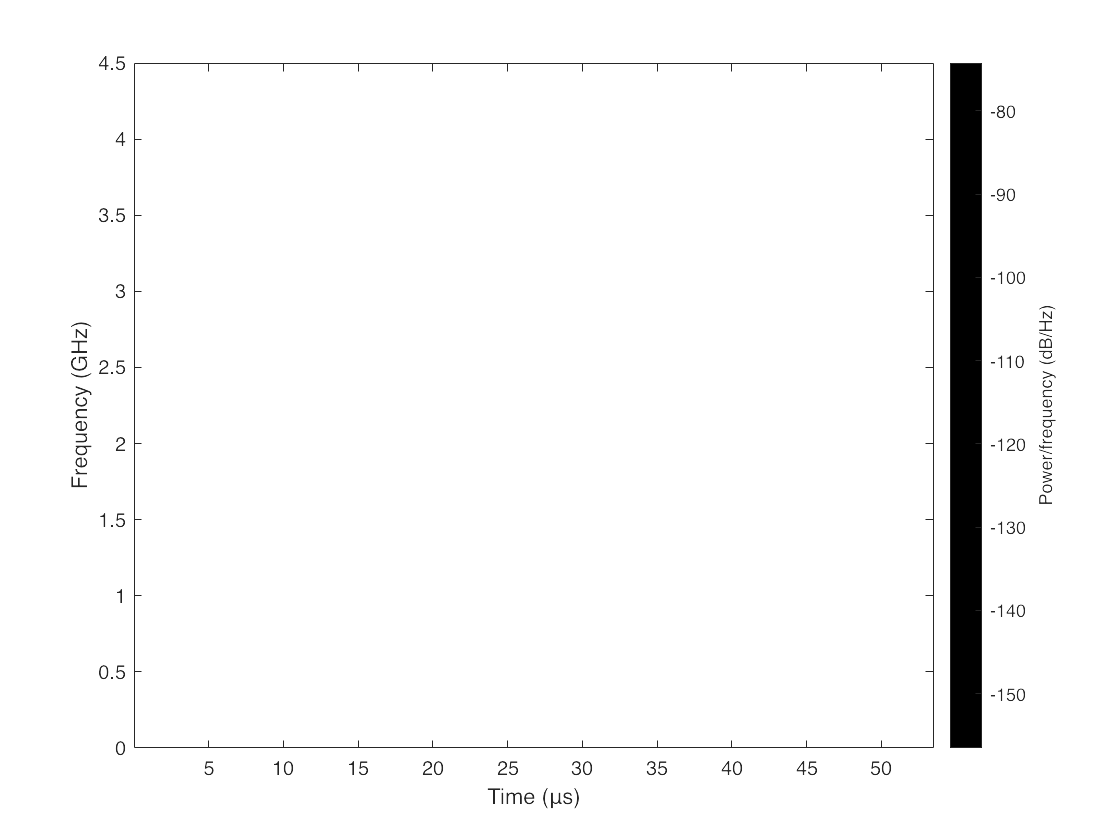


%spectogram
attacker.signal = attacker.waveform();
windowlength = 1028;
noverlap = 512;
nfft = 1028;
spectrogram(attacker.signal,windowlength,noverlap,nfft,attacker.sampling_rate, 'yaxis');
ylim([0 4.5])

### Implementing the attack

%set desired range to insert a false positive attack
attacker.desired_distance = 25;                                     %m

%calculate the time delay for the attack
attacker.time_delay = range2time(attacker.desired_distance,c)      %s

attacker = struct with fields:
                              fc: 7.7000e+10
                          lambda: 0.0039
                 frequency_slope: 65
                chirp_cycle_time: 6.7850e-05
                       idle_time: 7.0000e-06
            adc_valid_start_time: 6.3000e-06
                   ramp_end_time: 6.0850e-05
                 sampling_period: 5.3550e-05
                   sampling_rate: 2.0000e+10
               samples_per_chirp: 1071000
              sampling_bandwidth: 3.4808e+09
                        chirp_bw: 3.9552e+09
    Fs_for_256_samples_per_chirp: 4.7806e+06
                        waveform: [1×1 phased.FMCWWaveform]
                          signal: [1071000×1 double]
                desired_distance: 25
                      time_delay: 1.6678e-07


attacker.delay_in_samples = ceil(Fs_FMCW * attacker.time_delay);

%shift the attackers signal by the number of samples and then clip it to
%make sure that its the same number of samples

new_signal = zeros(defender.samples_per_chirp,1);
new_signal(attacker.delay_in_samples + 1: end) = ...
                attacker.signal(1:(attacker.samples_per_chirp - attacker.delay_in_samples));
attacker.signal = new_signal;

Next we plot the attacker's delayed signal to see what it looks like:

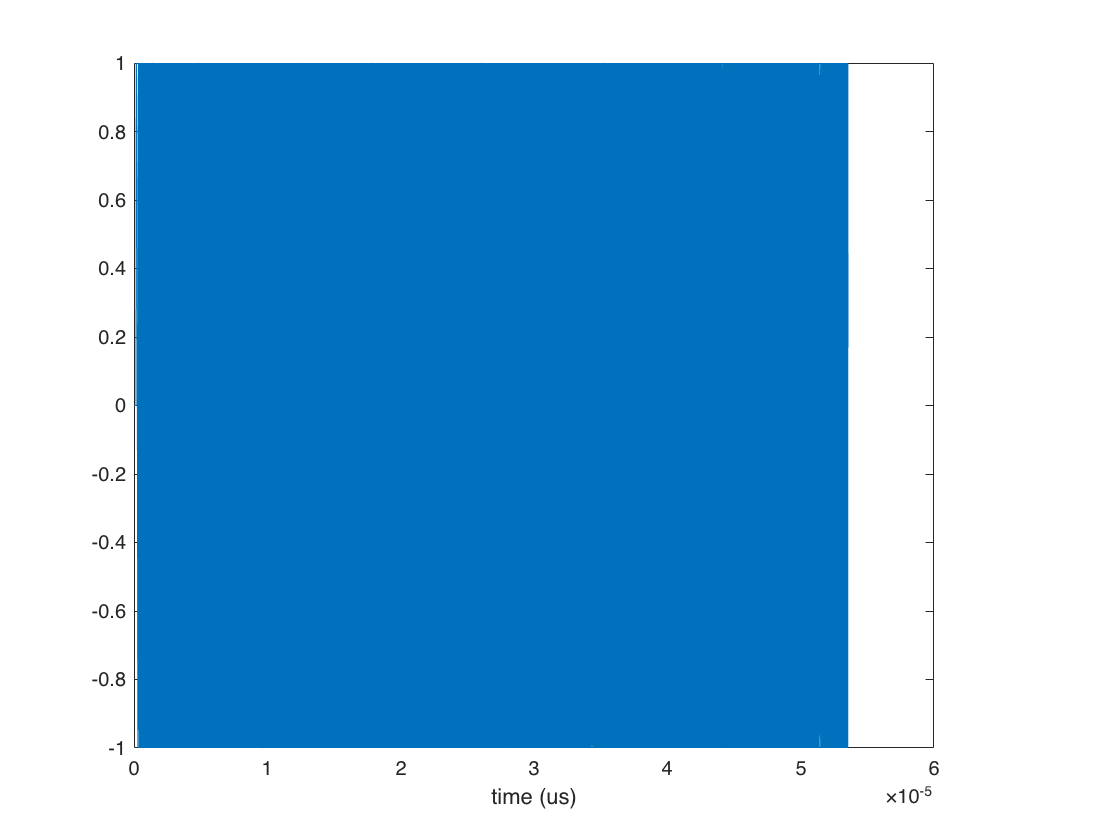

%time plot
t = 0:1/Fs_FMCW:attacker.sampling_period - 1/Fs_FMCW;
plot(t,real(attacker.signal)); 
xlabel('time (us)');

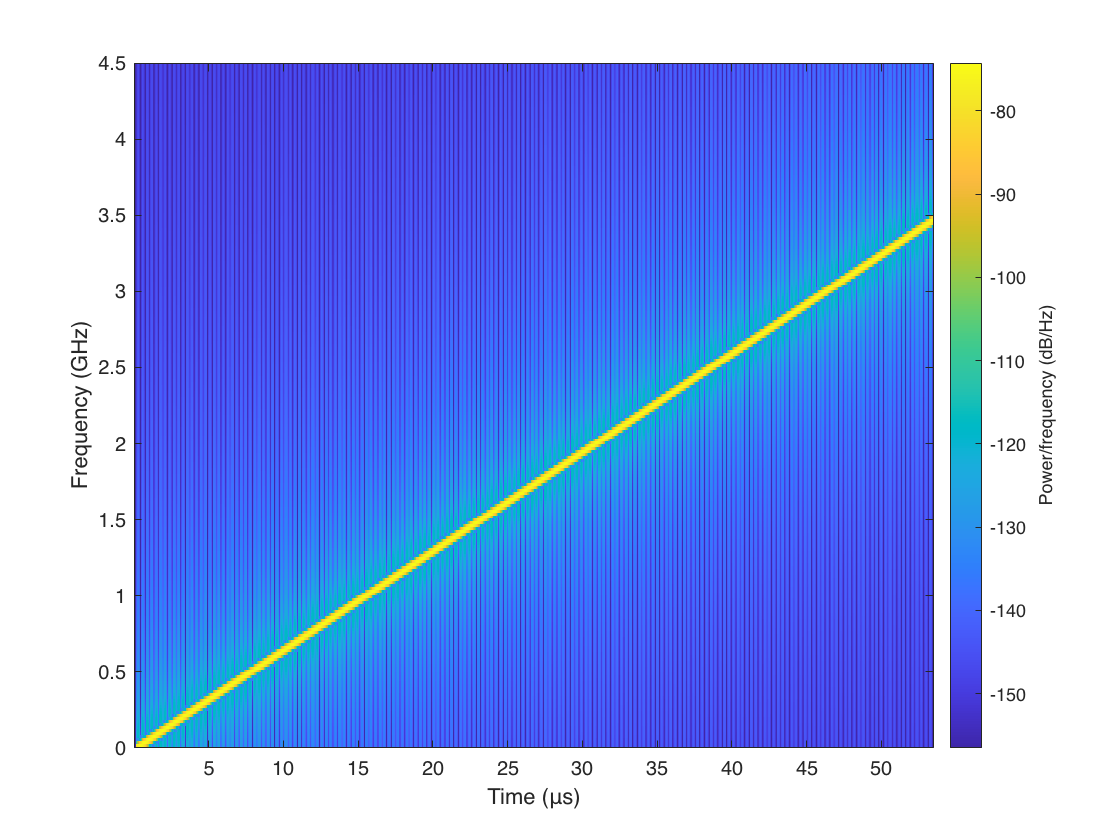


%spectogram
windowlength = 1028;
noverlap = 512;
nfft = 1028;
spectrogram(attacker.signal,windowlength,noverlap,nfft,Fs_FMCW, 'yaxis');
ylim([0 4.5])

### Evaluate how the attack affects the defender when calculating the range fft

First, we combine the attacker's signal with the signal received from the defender:

combined_signal = target.signal + attacker.signal;

Next, we dechirp the signal and look to see if we get a range on the target.

received_signal = dechirp(combined_signal,defender.signal);

We down sample the received signal as if it was being read by the ADC and DAC

%determine the nearest integer sampling factor by which to down sample the
%signal
down_sample_factor = ceil(Fs_FMCW/Fs_ADC_desired);
Fs_ADC_actual = Fs_FMCW / down_sample_factor;
received_signal_downsampled = downsample(received_signal,down_sample_factor);

Plot the received signal

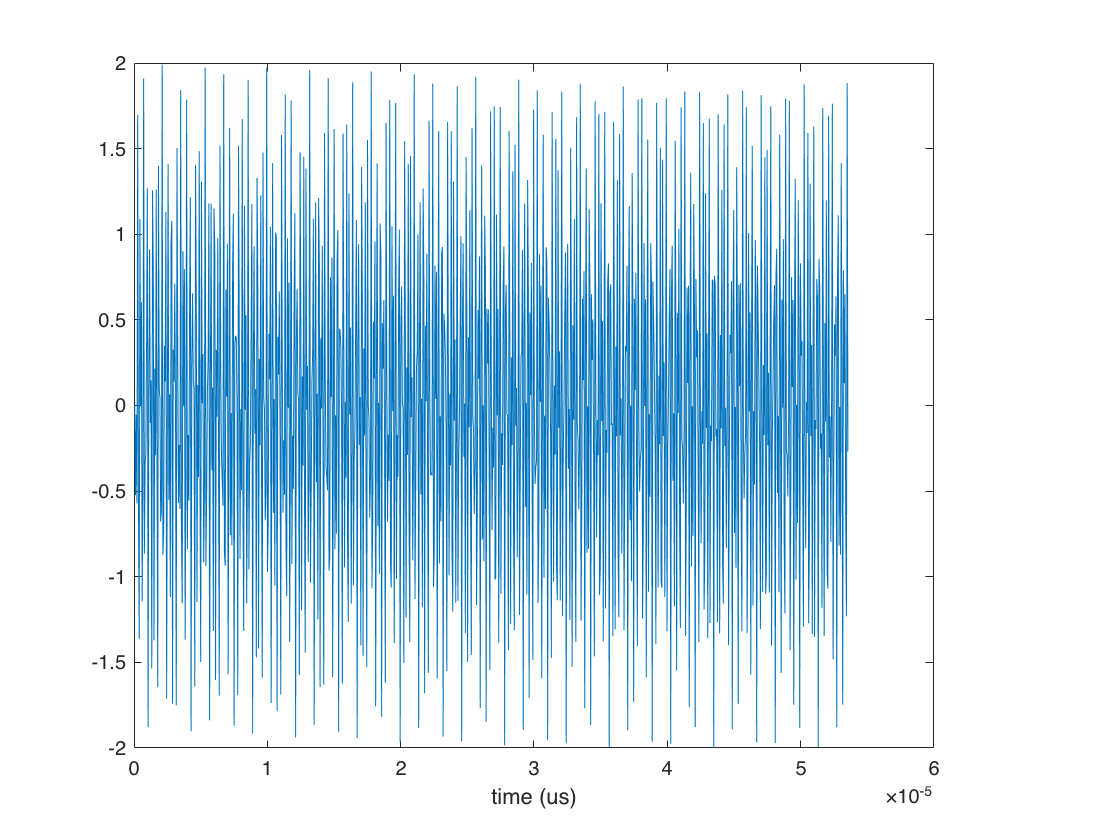

%time plot
ADC_sample_period = 1/Fs_ADC_actual;
num_downsampled_samples = ceil(defender.samples_per_chirp/down_sample_factor);
t = 0:ADC_sample_period:ADC_sample_period * (num_downsampled_samples-1);
plot(t,real(received_signal_downsampled)); 
xlabel('time (us)');

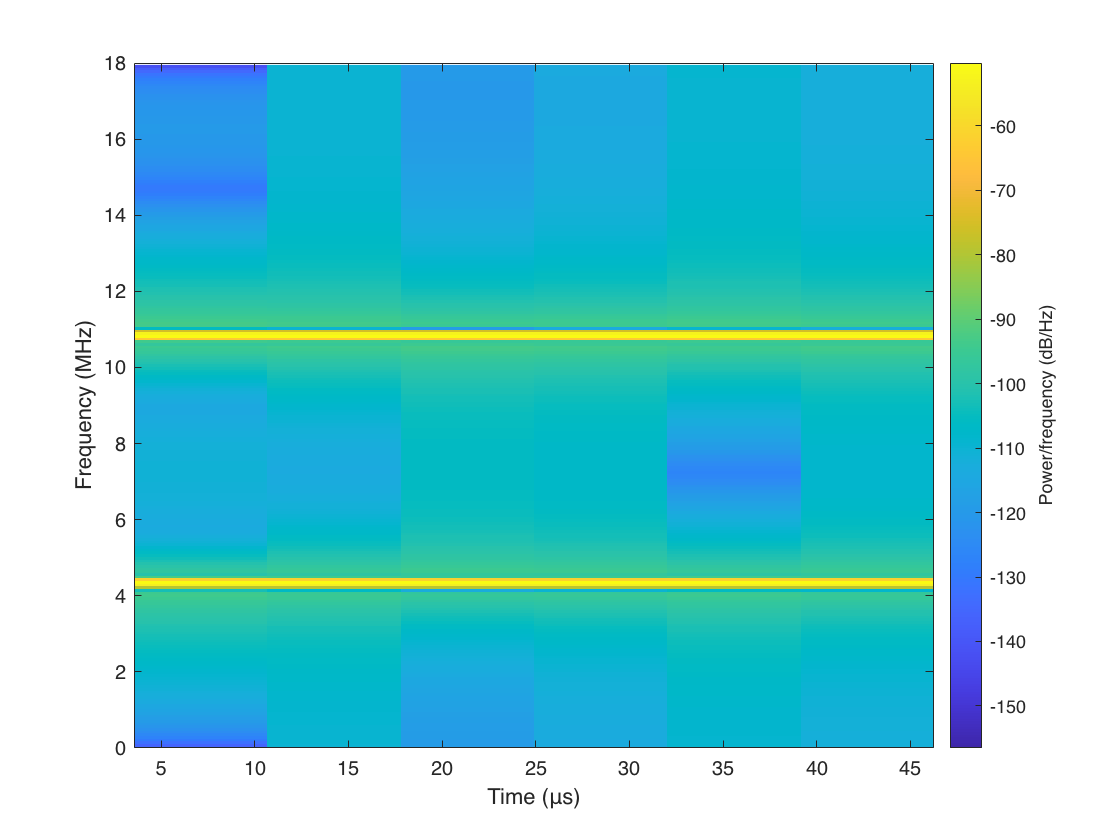

%spectogram
windowlength = 256;
noverlap = 128;
nfft = 256;
spectrogram(received_signal_downsampled,windowlength,noverlap,nfft,Fs_ADC_actual, 'yaxis');
ylim([0 18])

The spectograph clearly shows that we have a return from the attacker and a return from the defender, next we calculate the fft and determine the range of the target to confirm that we have accurately processed the signal:

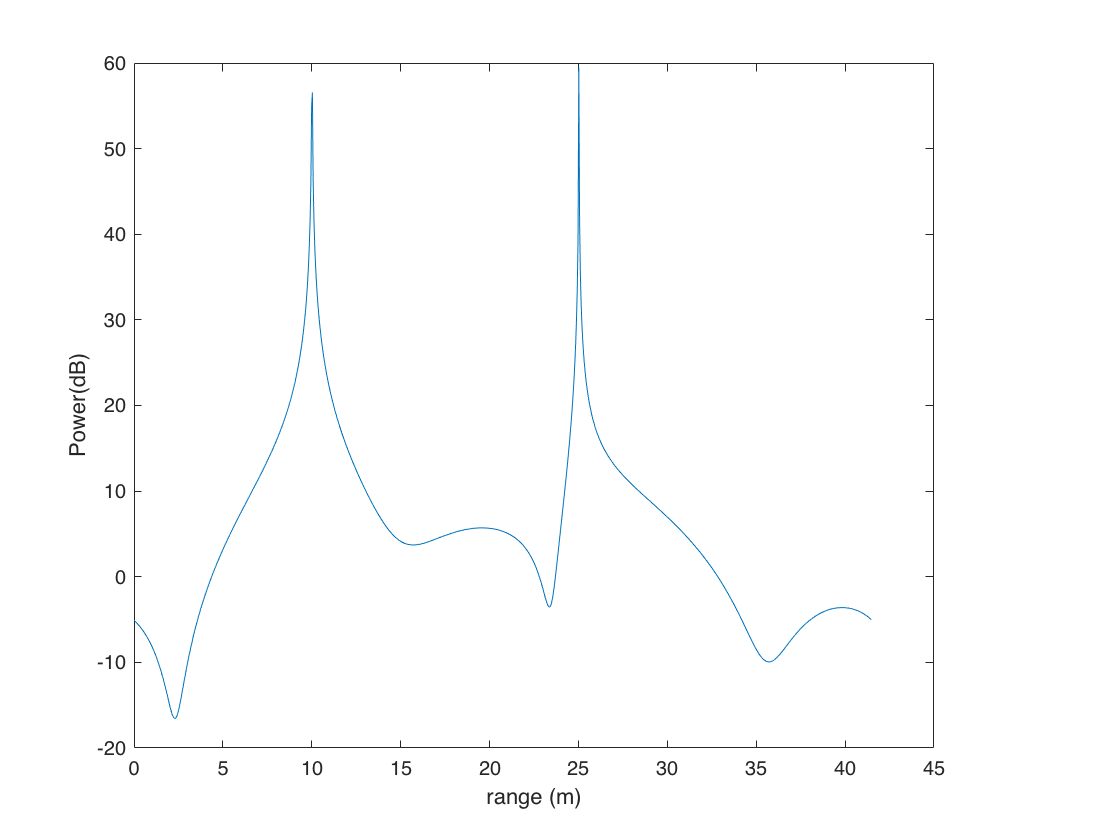

range_resolution = c/2/defender.sampling_bandwidth;
ranges = (0:num_downsampled_samples - 1) * range_resolution;

fft_out = 20 * log10(abs(fft(received_signal_downsampled)));
plot(ranges,fft_out)
ylabel("Power(dB)");
xlabel("range (m)");

From this, we can clearly see that we get a false positive return in the range fft. 